addpath("functions/");

# Simulation

save_to_file = true;

L = 50;
wait = 10e3;

save_cycles = 4;
steps = 10e3;


if ~exist("avalanche_sizes","var"); avalanche_sizes = []; end
filename = sprintf('data/%s_data_%s.mat',model,datestr(now,'mm-dd_HH-MM'));
for iter = 1:save_cycles
	
	% Model to run
	Manna

	avalanche_sizes = [avalanche_sizes; event_size];

	% Save to file if the box was checked
	if save_to_file; save(filename, "avalanche_sizes","z","L","steps", ...
			"wait","save_cycles","z_c","q","model");
	end
end


% Cleanup workspace
clear("nn_u","nn_r", "nn_l","nn_d","d_as","l_as","r_as","u_as","i","L_b", ...
	"count","wait_tmp","row_indices","events","event_size","iter", ...
	"active_sites","dice_roll","n_as","nn","delta_flat","delta")

# Post processing and plotting

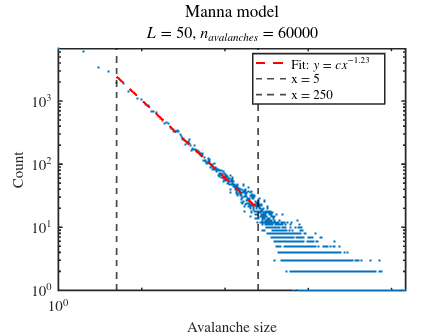

addpath("functions/");

if ~exist('avalanche_sizes','var'); load("/home/francesco/Documents/UNI/Sistemi complessi/SOC simulation/data/BTW_data_08-22_22-26.mat"); end

[sizes, count] = postprocess_data(avalanche_sizes);
subtitle = "$L = "+L+"$, $n_{avalanches} = "+numel(avalanche_sizes)+"$";
[fig,tau] = plot_avalanches(sizes,count,5,250,model+" model",subtitle);